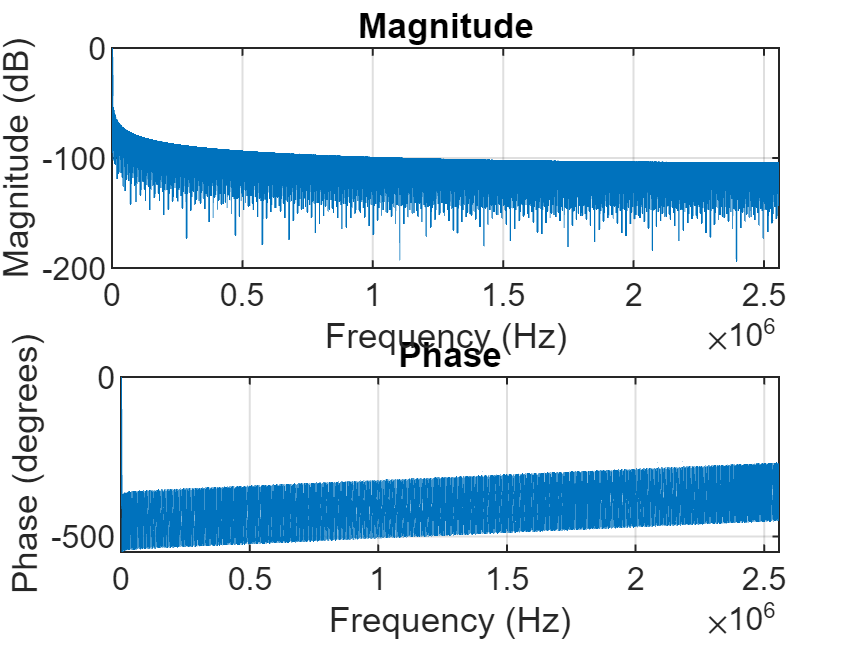

cutoff_frequency = 700; %Hz
sample_rate = 5 * 10^6 * 1.023; %Hz
filter_order = 6000;
h = fir1 (filter_order, cutoff_frequency / (0.5 * sample_rate), "low");
freqz (h, 1, 2^16, sample_rate);


part_1 = zeros (1, 6100);
part_2 = ones (1, 6100);
%x = [part_2 part_1];
x = [1000 part_1];
y = filter (h, 1, x);